# Main Function Facial Style Transfer

Nora's Portion

%Detect if there's a face in the content image and get the boundary of
%faces if there is one
content_image = imread("visionteam.jpg");

[Content_Face_Presence, bbox] = FaceDetection(content_image)

Content_Face_Presence = logical
   1


bbox =    344    45    43    43
   207    45    45    45
   469    62    45    45
   610    75    43    43
    60    75    47    47
   769    71    47    47


%Detect if there's a face in the style image and return boundaries of face
%if there is one
style_image = imread("starryNight.jpg");

[Style_Face_Presence, bbox] = FaceDetection(style_image)

Style_Face_Presence = logical
   0



bbox =

  0×4 empty double matrix



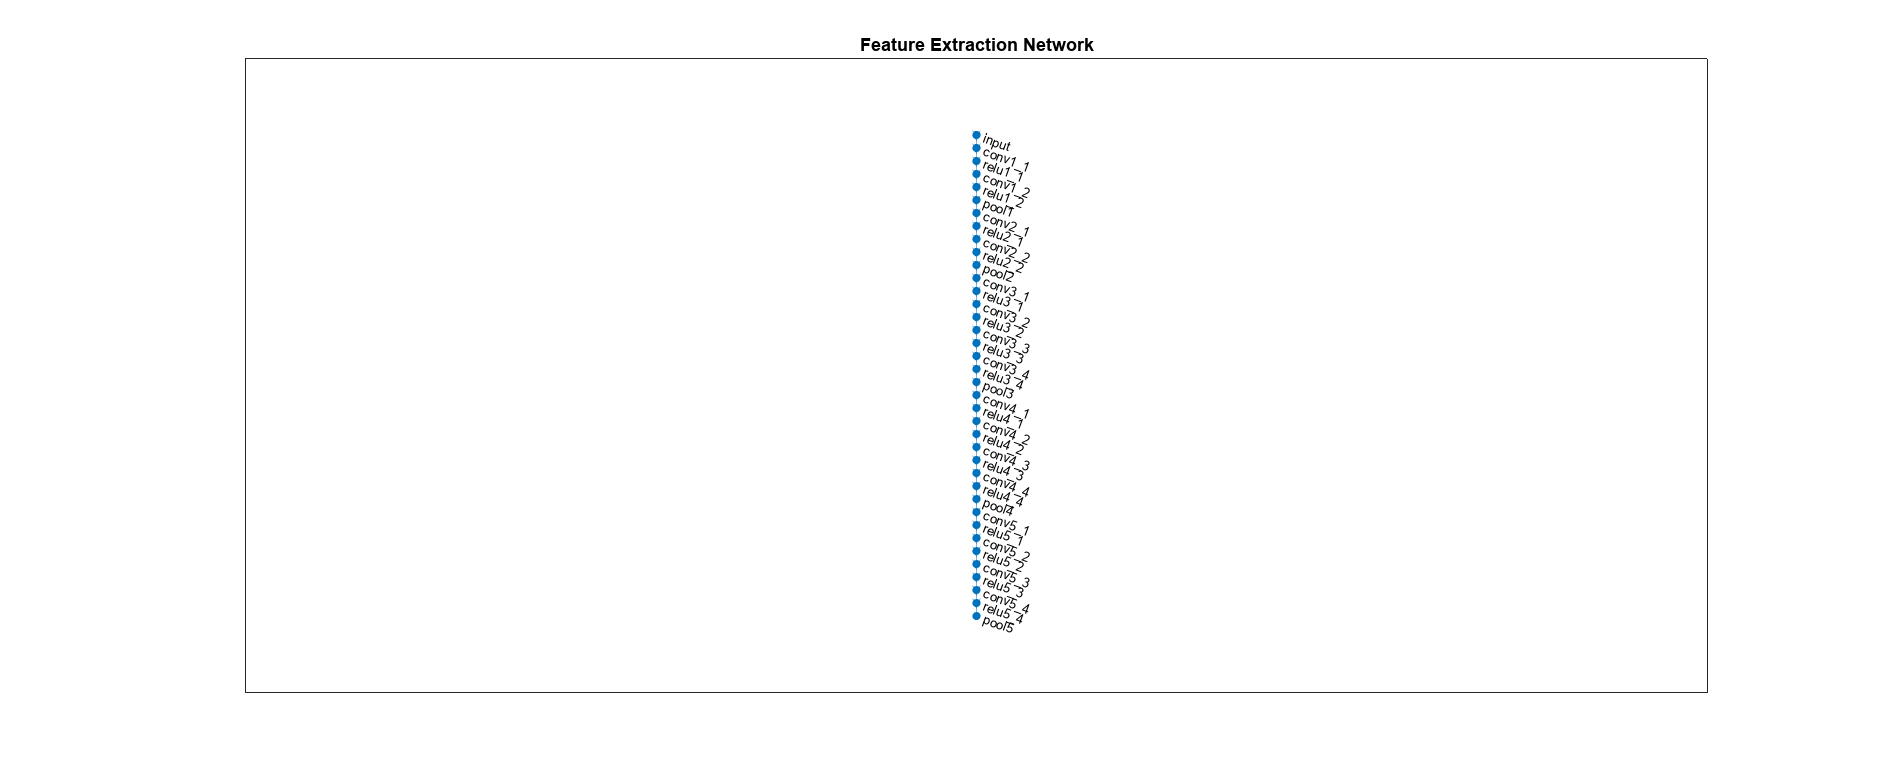

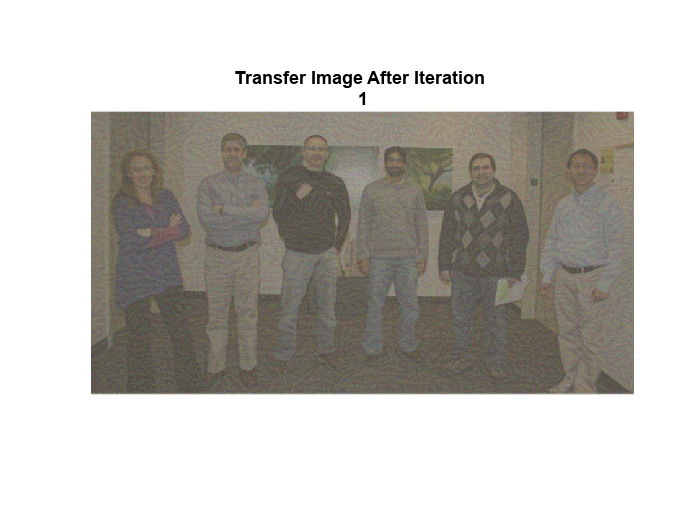

%If there is faces in both, use modified style transfer
if (Content_Face_Presence & Style_Face_Presence) == 1
    FaceStyleTransfer();
else
    %If only faces in one, default to normal style transfer
    NeuralStyleTransferUsingDeepLearningExample();
end